# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 21-Apr-2021 00:06:48

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 7);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["VarName1", "T", "spd", "pwr", "g_1", "g_2", "g_3"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
newdata = readtable("C:\физика\labs\2.3.1\new_data.csv", opts)

newdata = 3224×7 table
    VarName1    T     spd    pwr     g_1       g_2        g_3  
    ________    __    ___    ___    _____    _______    _______

        0        0    1.6    6.1    1e+05    9.9e+09    9.9e+09
        1        2    1.6      8    1e+05    9.9e+09    9.9e+09
        2        4    1.6    7.5    1e+05    9.9e+09    9.9e+09
        3        6    1.6      8    1e+05    9.9e+09    9.9e+09
        4        9    1.6    8.4    1e+05    9.9e+09    9.9e+09
        5       10    1.6    7.5    1e+05    9.9e+09    9.9e+09
        6       13    1.6    8.4    1e+05    9.9e+09    9.9e+09
        7       15    1.6      8    1e+05    9.9e+09    9.9e+09
        8       17    1.6    5.8    1e+05    9.9e+09    9.9e+09
        9       19    1.6    6.1  

## Clear temporary variables

clear opts

hold on
grid on
x_1 = newdata.T([71:84]);
y_1 = log(newdata.g_1([71:84]));
x_2 = newdata.T(85:100)

x_2 =    173
   175
   177
   179
   182
   184
   186
   188
   190
   192


y_2 = log(newdata.g_1(85:100));
plot(x_1,y_1,"+r");
plot(x_2,y_2,"+black")
xi = min(135):0.1:max(180);
coeff1 = polyfit(x_1,y_1, 1)

coeff1 =    -0.2651   48.4180


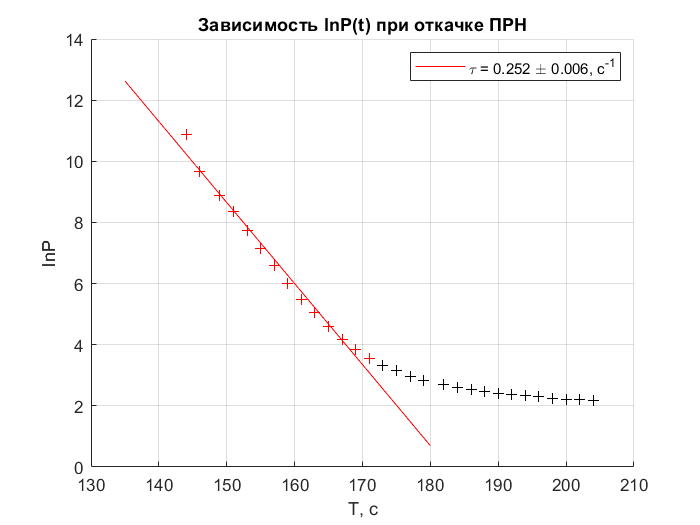

y1 = 0;
for k=0:1
    y1 = y1 + coeff1(1-k+1) * xi.^k;
end
gr1 = plot(xi, y1, 'r'); 
title("Зависимость lnP(t) при откачке ПРН")
xlabel('T, с')
ylabel('lnP')
legend([gr1], {'\tau = 0.252 \pm 0.006, c^{-1}'})
hold off 

cla reset


hold on
grid on 

x_3 = newdata.T(2470:2512);
y_3 = log(newdata.g_2(2470:2512));
x_4 = newdata.T(2425:2470);
y_4 = log(newdata.g_2(2425:2470));
plot(x_3,y_3,"+r");
plot(x_4,y_4,"+black")
x_i = min(5000):0.1:max(5175);
coeff2 = polyfit(x_3,y_3, 1)

coeff2 =    -0.0051   19.2716


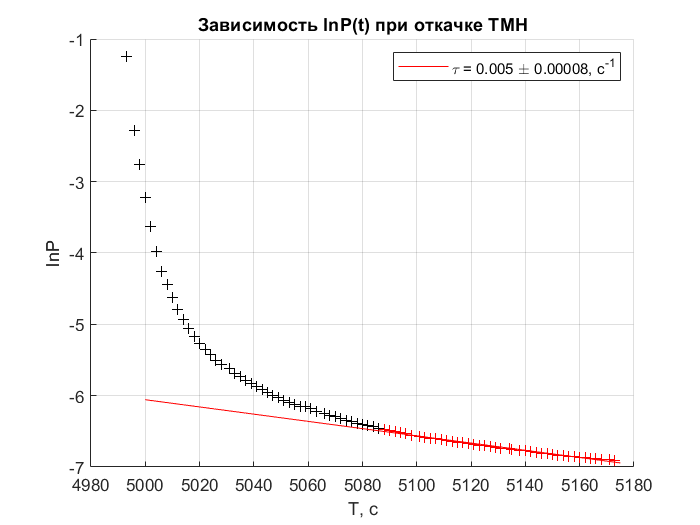

y1 = 0;
for k=0:1
    y1 = y1 + coeff2(1-k+1) * x_i.^k;
end
gr2 = plot(x_i, y1, 'r'); 
title("Зависимость lnP(t) при откачке ТМН")
xlabel('T, с')
ylabel('lnP')
legend([gr2], {'\tau = 0.005 \pm 0.00008, c^{-1}'})
hold off 